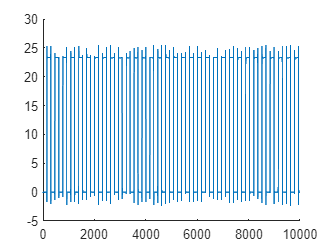

f1=figure;
hold on
plot(cyl06_35.original)
xlim([0,10000])
hold off

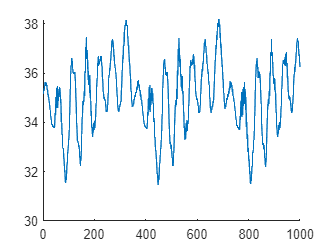


f2=figure;
hold on
plot(cyl06_35.ori_rpm)
xlim([0,1000])
hold off

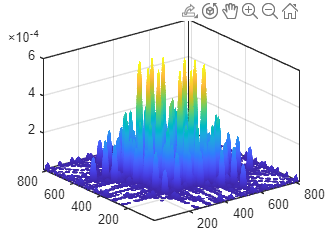

contour3(abs(reduce_Bspec_cyl06_45),500)




t=reduce_Bspec_cyl06_45(405:820,405:820)

t = 	1.0e+-3 *

  -0.0086 + 0.0008i  -0.0076 + 0.0001i  -0.0058 - 0.0009i  -0.0044 - 0.0010i  -0.0035 - 0.0008i  -0.0029 - 0.0004i  -0.0028 - 0.0002i  -0.0027 - 0.0000i  -0.0027 + 0.0001i  -0.0026 + 0.0003i  -0.0025 + 0.0004i  -0.0025 + 0.0004i  -0.0026 + 0.0003i  -0.0027 + 0.0001i  -0.0027 - 0.0000i  -0.0028 - 0.0002i  -0.0029 - 0.0004i  -0.0035 - 0.0008i  -0.0044 - 0.0010i  -0.0058 - 0.0009i  -0.0076 + 0.0001i  -0.0086 + 0.0008i  -0.0094 + 0.0014i  -0.0113 + 0.0024i  -0.0127 + 0.0035i  -0.0111 + 0.0080i  -0.0043 + 0.0032i   0.0045 + 0.0076i   0.0092 + 0.0080i   0.0139 + 0.0087i   0.0177 + 0.0086i   0.0216 + 0.0091i   0.0243 + 0.0093i   0.0257 + 0.0095i   0.0267 + 0.0091i   0.0263 + 0.0083i   0.0256 + 0.0072i   0.0237 + 0.0065i   0.0206 + 0.0059i   0.0163 + 0.0061i   0.0095 + 0.0012i  -0.0010 + 0.0029i  -0.0010 + 0.0011i  -0.0022 + 0.0008i  -0.0032 + 0.0003i  -0.0021 - 0.0005i  -0.0016 - 0.0008i  -0.0013 - 0.0008i  -0.0014 + 0.0000i  -0.0007 - 0.0005i
  -0.0076 + 0.0001i  -0.0059 - 0.

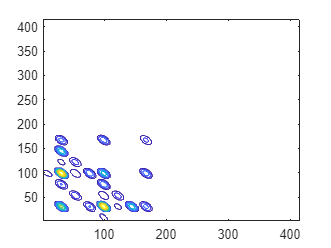

contour(abs(t),10)

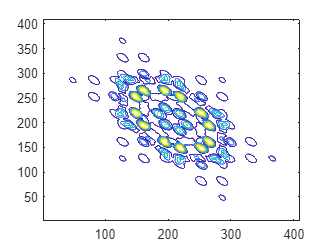

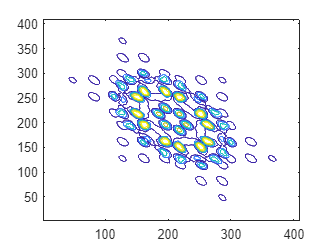

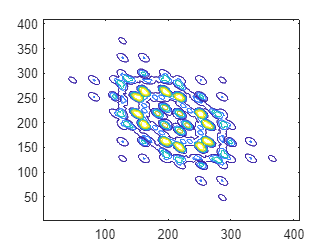

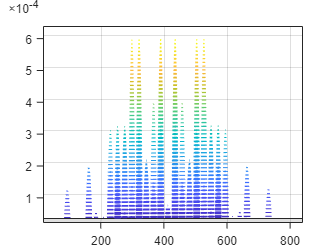



xline(0)
yline(0)

% xlim([0,0.05])
% ylim([0,0.05])

sum_data=zeros(21,411)

sum_data =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0  

data=abs(reduce_Bspec_cyl06_45)

data = 	1.0e+-3 *

    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0002    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0002    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000

k=1;

data=data((length(data)/2)+1:length(data),(length(data)/2)+1:length(data));
len=length(data)

len = 410


for i= 1:len
    if i<=len/2
        for j=1:i
            sum_data(k,i)=sum_data(k,i)+data(j,i);
        end
    elseif i>len/2
        for j=1:len-i
            sum_data(k,i)=sum_data(k,i)+data(j,i);
        end

    end
    
end

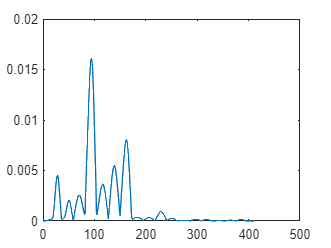


plot(sum_data(1,:))